# Ploteo en Matlab

## 1. Ploteo en dos dimensiones

**Ejemplo:**

Plotear la función $f(x)=(4x^3-2x^2-x-1)\sin(x), \; -2\le x \le 2.$

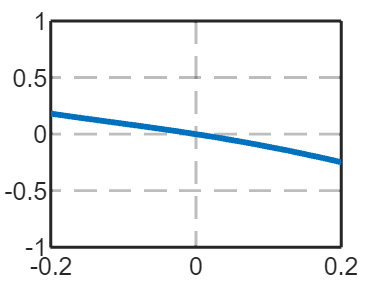

%x = -2:0.03:2;
x = linspace(-2,2,80);
y = (4*x.^3-2*x.^2-x-1).*sin(x);
plot(x,y,'LineWidth',2)
axis([-0.2,0.2,-1,1])
grid on

**Ejemplo:**

Ploteamos 3 funciones a la vez en la misma ventana


$$f_1(x)=x^2 \cos(x),\; f_2(x) = x \cos(x),\; f_3(x) = 2^x \sin(x),$$


con x en $[0,2\pi].$

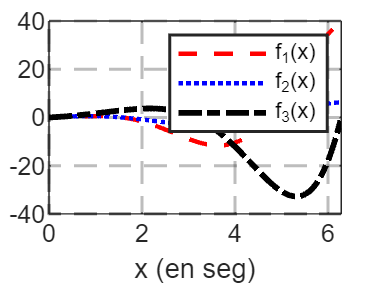

x = linspace(0,2*pi);
f1 = x.^2 .* cos(x);
f2 = x.*cos(x);
f3 = 2.^x.*sin(x);
%plot(x,f1,'r--',x,f2,'b:',x,f3,'k-.','LineWidth',2)
plot(x,f1,'r--'), hold on
plot(x,f2,'b:')
plot(x,f3,'k-.','LineWidth',2), hold off
grid on, xlabel('x (en seg)')
legend('f_1(x)','f_2(x)','f_3(x)')

## 2. Comandos extras para ploteos: loglog, semilogx, semilogy, area, fplot

Dados dos arreglos unidimensionales, x, y

- `loglog(x,y)` es un ploteo con escala logaritmica en ambos ejes

- `semilogx(x,y)` es un ploteo con escala logaritmica solo en el eje horizontal

- `area(x,y) `da un sombreo de la región acotada por la gráfica de la función y el eje horizontal.

- `fplot('fun',[xmin,xmax])`

**Ejemplo:**

Plotear $g_1(x) = 2x+30, \; g_2(t) = \sin(t) \cos(2t),$

en el dominio [0,100]

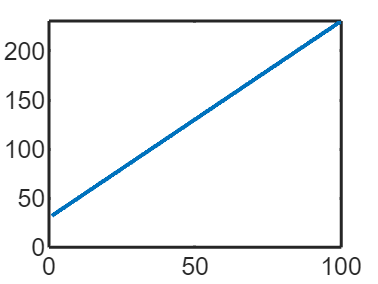

x = 1:0.1:100;
g1 = 2*x+30;
plot(x,g1)

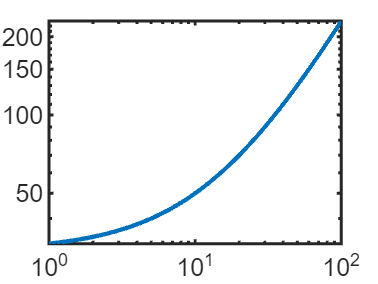


loglog(x,g1)

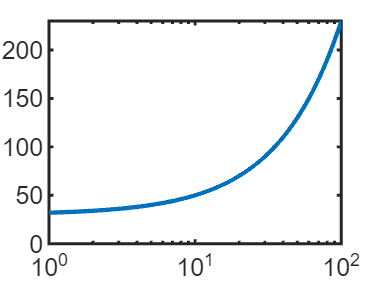


semilogx(x,g1)

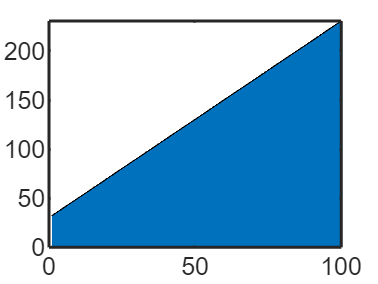


area(x,g1)

Definimos g_2(t) de manera anónima.

`g2 = @(t) sin(t).*cos(2*t);`

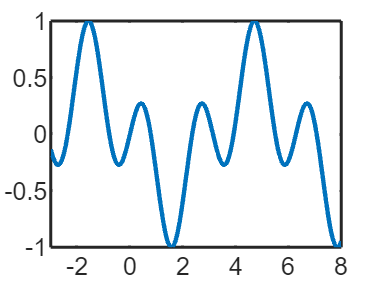

g2 = @(t) sin(t).*cos(2*t);
%a = [0.3, 4, -5];
%g2(a)
fplot(g2,[-3,8])  % ezplot

## 3. Ploteo de señales discretas (uso del comando stem)

Si tenemos la señal discreta $f[n] = n^3+2n^2$, n en [n0,n1], para plotearlo usamos:

`n = n0:n1;`

`f = n.^3+2*n.^2;`

`stem(n,f)`

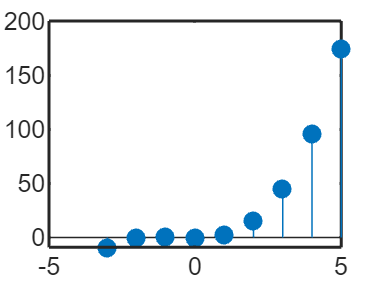

n = -3:5;
f = n.^3+2*n.^2;
stem(n,f,'filled')

%stem(n,f,'rs')

## 4. Ploteo de funciones definidas por tramos

**Ejemplo:** Plotear la función


$$f(t) = \begin{cases}
1, & -2 \le t\le 2, \\
0, & 2 < t < 5, \\
t \sin(4\pi t), & 5\le t \le 8.
\end{cases}$$


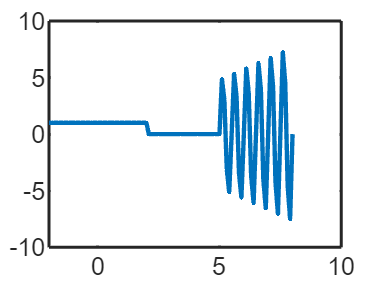

dt = 0.1;
t1 = -2:dt:2;
t2 = 2.1:dt:4.9;
t3 = 5:dt:8;

f1 = ones(size(t1));
f2 = zeros(size(t2));
f3 = t3.*sin(4*pi*t3);

t = [t1,t2,t3];  % arreglo de abscisas
f = [f1,f2,f3];  % arreglo de ordenadas

plot(t,f)

**Ejemplo:** Plotear la función


$$g(t) = \begin{cases}
t e^{-t}, & -2 \le t\le 2, \\
\cos(t), & 2 < t < 5, \\
e^{-t} \sin(t), & 5\le t \le 8.
\end{cases}$$


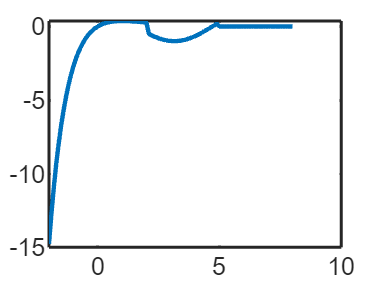

dt = 0.1;
t1 = -2:dt:2;
t2 = 2.1:dt:4.9;
t3 = 5:dt:8;

g1 = t1.*exp(-t1);
g2 = cos(t2);
g3 = exp(-t3).*sin(t3);

t = [t1,t2,t3];  % arreglo de abscisas
g = [g1,g2,g3];  % arreglo de ordenadas

plot(t,g)

Otra forma es reescribir g en una sola línea usando la función de Heaviside y de forma anónima:

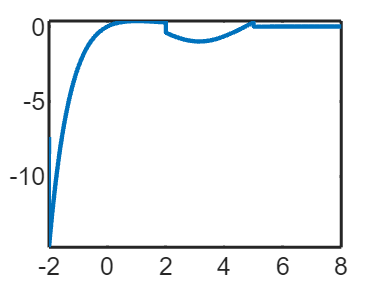

g = @(t) t.*exp(-t).*heaviside(t+2)+(cos(t)-t.*exp(-t)).*heaviside(t-2)+(exp(-t).*sin(t)-cos(t)).*heaviside(t-5)+exp(-t).*sin(t).*heaviside(t-8);
fplot(g,[-2,8])

# Cálculo Simbólico

Para realizar cálculo simbólico o exacto en Matlab, primero debemos definir las variables que vamos a usar de manera simbólica por medio del comando `syms` (si hay más de una variable, separarlas con espacio en blanco, no usar comas).

syms x
limit(sin(x)/x,0)

$$ans = 1$$


syms y z w
A = [x, 2*y; z-w, z+w]

$$A = \left(\begin{array}{cc} x & 2\,y\\ z-w & w+z \end{array}\right)$$

det(A)

$$ans = w\,x+2\,w\,y+x\,z-2\,y\,z$$

## 1. Derivada de una función

Si tenemos una función f(x) entonces debemos declarar primero x de manera simbólica

Sintaxis:

`diff(f)`

`diff(f,n)`  % derivada n-esima

Si f es una función de dos o más variables, usamos

`diff(f,variable,n)`

**Ejemplo:**

Calcule las primeras y segundas derivadas parciales de $f(x,y) = e^{-x} \cos(y)$

clear x y f 
syms x y
f = exp(-x)*cos(y);
diff(f,x)

$$ans = -{\mathrm{e}}^{-x}\,\cos\left(y\right)$$

diff(f,y)

$$ans = -{\mathrm{e}}^{-x}\,\sin\left(y\right)$$

diff(f,x,2) % segunda derivada parcial respecto a x

$$ans = {\mathrm{e}}^{-x}\,\cos\left(y\right)$$

diff(f,y,2)

$$ans = -{\mathrm{e}}^{-x}\,\cos\left(y\right)$$

diff(diff(f,x),y) % 2da der. parcial respecto a x, y

$$ans = {\mathrm{e}}^{-x}\,\sin\left(y\right)$$

## 2. Integración de una función

Sintaxis:

`int(f,variable)`  % integral indefinida

`int(f,variable,lim_inf,lim_sup)` % integral definida

**Ejemplo:**

Considerar $f(x) =x^2,\; g(x,t) = x^2+e^{-t}.$ Calcule


$$\int f(x)\, dx, \quad\int_{-1}^1 f(x) \, dx.$$


clear x t f
syms x t
f = x^2;
g = x^2+exp(-t);
int(f,x)

$$ans = \frac{x^{3}}{3}$$


int(f,x,-1,1)

$$ans = \frac{2}{3}$$

Calcule $\int\int g(x,t) dx\, dt$

z = int(g,x)

$$z = \frac{x^{3}}{3}+{\mathrm{e}}^{-t}\,x$$

int(z,t)

$$ans = \frac{t\,x^{3}}{3}-x\,{\mathrm{e}}^{-t}$$

## 3. Suma de una serie (uso de symsum)

La sintaxis es:

`symsum(expr,indice,lim_inf,lim_sup)`

**Ejemplo:**

Calcule $\displaystyle\sum_{n=0}^{\infty} x^n$

clear x n
syms x n
f = x^n;
symsum(f,n,0,inf)

$$ans = \left\{ \begin{array}{cl} \infty & \text{ if }1\leq x\\ -\frac{1}{x-1} & \text{ if }\left|x\right|<1 \end{array}\right.$$

## 4. Solución de ecuaciones algebraicas

El uso del comando `solve`

**Ejemplo:**

Resolver $x^3+6x+5=0.$

clear x
syms x
ecua = x^3+6*x+5;
rpta = solve(ecua,x)

$$rpta = \left(\begin{array}{c} \mathrm{root}\left(z^{3}+6\,z+5,z,1\right)\\ \mathrm{root}\left(z^{3}+6\,z+5,z,2\right)\\ \mathrm{root}\left(z^{3}+6\,z+5,z,3\right) \end{array}\right)$$

vpa(rpta,10) % forzamos a que las rptas simbólicas

$$ans = \left(\begin{array}{c} -0.7601324178\\ 0.3800662089-2.536405127\,\mathrm{i}\\ 0.3800662089+2.536405127\,\mathrm{i} \end{array}\right)$$

  % se conviertan a rptas numéricas con 10 cifras de
  % exactitud

**Ejemplo:**

Resolver el sistema lineal: $y=2x+3, \; y=4x+5.$

clear x y
syms x y
solve(y==2*x+3,y==4*x+5,x,y)

ans = struct with fields:
    x: -1
    y: 1

## 5. El comando subs (sustitución)

Este comando es usado para reemplazar una o más variables (símbólicas o numéricas) de una expresión simbólica con otras. La sintaxis es:

`subs(f,viejas,nuevas)`

donde `f` es la expresión, `viejas` son las variables a ser reemplazadas, y `nuevas` son las variables que reemplazarán a las viejas. Veamos un ejemplo:

syms x y z
f = 2*x+y+4  % f es una expresión simbólica de dos variables simbólicas

$$f = 2\,x+y+4$$

w = subs(f,y,3) % se reemplaza y por 3, en la formula para f

$$w = 2\,x+7$$

q = subs(w,x,z) % se reemplaza x por z, en la formula para w

$$q = 2\,z+7$$

subs(q,7,11)  % el número 7 es reemplazado por 11

$$ans = 2\,z+11$$

subs(f,[x,y],[z,3]) % reemplazo x->z, y->3, en la formula para f

$$ans = 2\,z+7$$

## 6. Solución de Ecuaciones Diferenciales Ordinarias

La clave es saber usar el comando dsolve, el cual pertenece a la Symbolic Math toolbox.

**Ejemplo:**

Halle la **solución general **de la ecuación diferencial lineal:


$$y^{(4)}(t)+10y^{(3)}(t)+35 y''(t)+50y'(t)+24y(t) = 5 u''(t)+4u'(t)+2 u(t),$$


donde la señal de entrada viene dada por


$$u(t) = e^{-5t}  \cos(2t+1)+5.$$


syms t y(t)
u = exp(-5*t)*cos(2*t+1)+5;
uu = 5*diff(u,t,2)+4*diff(u,t)+2*u;
ecua = diff(y,4)+10*diff(y,3)+35*diff(y,2)+50*diff(y)+24*y==uu;
ySol(t) = dsolve(ecua)

$$ySol(t) = \begin{array}{l} \frac{{\mathrm{e}}^{-5\,t}\,\left(445\,\sigma_{2}-65\,{\mathrm{e}}^{5\,t}+102\,\sigma_{1}\right)}{26}-\frac{{\mathrm{e}}^{-5\,t}\,\left(537\,\sigma_{2}-40\,{\mathrm{e}}^{5\,t}+15\,\sigma_{1}\right)}{24}-\frac{{\mathrm{e}}^{-5\,t}\,\left(25\,{\mathrm{e}}^{5\,t}-542\,\sigma_{2}+164\,\sigma_{1}\right)}{60}-{\mathrm{e}}^{-t}\,\left(\frac{133\,{\mathrm{e}}^{-4\,t}\,\sigma_{2}}{30}-\frac{5\,{\mathrm{e}}^{t}}{3}+\frac{97\,{\mathrm{e}}^{-4\,t}\,\sigma_{1}}{60}\right)+C_{1}\,{\mathrm{e}}^{-4\,t}+C_{2}\,{\mathrm{e}}^{-3\,t}+C_{3}\,{\mathrm{e}}^{-2\,t}+C_{4}\,{\mathrm{e}}^{-t}\\ \mathrm{where}\\ \sigma_{1}=\sin\left(2\,t+1\right)\\ \sigma_{2}=\cos\left(2\,t+1\right) \end{array}$$

simplify(ySol(t))  % a veces es bueno simplificar un poco más la solución

$$ans = C_{1}\,{\mathrm{e}}^{-4\,t}-\frac{547\,{\mathrm{e}}^{-5\,t}\,\sin\left(2\,t+1\right)}{520}-\frac{343\,{\mathrm{e}}^{-5\,t}\,\cos\left(2\,t+1\right)}{520}+C_{2}\,{\mathrm{e}}^{-3\,t}+C_{3}\,{\mathrm{e}}^{-2\,t}+C_{4}\,{\mathrm{e}}^{-t}+\frac{5}{12}$$

   % obtenida.

También es posible resolver ecuaciones diferenciales con condiciones iniciales (problemas de valor inicial). 

**Ejemplo:** Considere la EDO lineal anterior pero ahora suponga que se tienen las siguientes condiciones iniciales:


$$y(0)=3, \; y'(0)=2, \; y''(0)=y^{(3)}(0)=0.$$


% aprovechemos que ya está en memoria la ecuación, 
% así que solo debemos especificar las condiciones iniciales
Dy = diff(y); D2y = diff(y,2); D3y = diff(y,3);
cond = [y(0)==3,Dy(0)==2,D2y(0)==0,D3y(0)==0];
ySol(t) = dsolve(ecua,cond)

$$ySol(t) = \frac{{\mathrm{e}}^{-5\,t}\,\left(37960\,{\mathrm{e}}^{2\,t}-53820\,{\mathrm{e}}^{3\,t}+29640\,{\mathrm{e}}^{4\,t}+650\,{\mathrm{e}}^{5\,t}-1029\,\cos\left(2\,t+1\right)-1641\,\sin\left(2\,t+1\right)-9750\,{\mathrm{e}}^{t}+975\,{\mathrm{e}}^{2\,t}\,\sin\left(1\right)-6120\,{\mathrm{e}}^{3\,t}\,\sin\left(1\right)+2522\,{\mathrm{e}}^{4\,t}\,\sin\left(1\right)-14092\,\cos\left(1\right)\,{\mathrm{e}}^{t}+4264\,{\mathrm{e}}^{t}\,\sin\left(1\right)+34905\,\cos\left(1\right)\,{\mathrm{e}}^{2\,t}-26700\,\cos\left(1\right)\,{\mathrm{e}}^{3\,t}+6916\,\cos\left(1\right)\,{\mathrm{e}}^{4\,t}\right)}{1560}$$

f(t) = simplify(ySol(t))

$$f(t) = 19\,{\mathrm{e}}^{-t}-\frac{69\,{\mathrm{e}}^{-2\,t}}{2}+\frac{73\,{\mathrm{e}}^{-3\,t}}{3}-\frac{25\,{\mathrm{e}}^{-4\,t}}{4}+\frac{97\,{\mathrm{e}}^{-t}\,\sin\left(1\right)}{60}-\frac{51\,{\mathrm{e}}^{-2\,t}\,\sin\left(1\right)}{13}+\frac{5\,{\mathrm{e}}^{-3\,t}\,\sin\left(1\right)}{8}+\frac{41\,{\mathrm{e}}^{-4\,t}\,\sin\left(1\right)}{15}-\frac{343\,{\mathrm{e}}^{-5\,t}\,\cos\left(2\,t+1\right)}{520}-\frac{547\,{\mathrm{e}}^{-5\,t}\,\sin\left(2\,t+1\right)}{520}+\frac{133\,\cos\left(1\right)\,{\mathrm{e}}^{-t}}{30}-\frac{445\,\cos\left(1\right)\,{\mathrm{e}}^{-2\,t}}{26}+\frac{179\,\cos\left(1\right)\,{\mathrm{e}}^{-3\,t}}{8}-\frac{271\,\cos\left(1\right)\,{\mathrm{e}}^{-4\,t}}{30}+\frac{5}{12}$$

Es útil saber que cuando usamos syms y(t), tenemos la particularidad de indicar que la variable simbólica y depende de t (podríamos pensar que hemos construido una función anónima de t ... pero no es lo mismo).

En la última línea del código de arriba simplificamos la solución de la EDO y la almacenamos en memoria como una función simbólica f de t. Hecho esto, podemos evaluarla (en escalares o arreglos), convertir los cálculos exactos en expresiones numéricas (comando vpa), e inclusive plotear la función:

a = f(4) 

$$a = 19\,{\mathrm{e}}^{-4}-\frac{69\,{\mathrm{e}}^{-8}}{2}+\frac{73\,{\mathrm{e}}^{-12}}{3}-\frac{25\,{\mathrm{e}}^{-16}}{4}+\frac{133\,\cos\left(1\right)\,{\mathrm{e}}^{-4}}{30}-\frac{445\,\cos\left(1\right)\,{\mathrm{e}}^{-8}}{26}+\frac{179\,\cos\left(1\right)\,{\mathrm{e}}^{-12}}{8}-\frac{271\,\cos\left(1\right)\,{\mathrm{e}}^{-16}}{30}-\frac{343\,\cos\left(9\right)\,{\mathrm{e}}^{-20}}{520}+\frac{97\,{\mathrm{e}}^{-4}\,\sin\left(1\right)}{60}-\frac{51\,{\mathrm{e}}^{-8}\,\sin\left(1\right)}{13}+\frac{5\,{\mathrm{e}}^{-12}\,\sin\left(1\right)}{8}+\frac{41\,{\mathrm{e}}^{-16}\,\sin\left(1\right)}{15}-\frac{547\,{\mathrm{e}}^{-20}\,\sin\left(9\right)}{520}+\frac{5}{12}$$

b = f([1,3])

$$b = \left(\begin{array}{cc} 19\,{\mathrm{e}}^{-1}-\frac{69\,{\mathrm{e}}^{-2}}{2}+\frac{73\,{\mathrm{e}}^{-3}}{3}-\frac{25\,{\mathrm{e}}^{-4}}{4}+\frac{133\,\cos\left(1\right)\,{\mathrm{e}}^{-1}}{30}-\frac{445\,\cos\left(1\right)\,{\mathrm{e}}^{-2}}{26}+\frac{179\,\cos\left(1\right)\,{\mathrm{e}}^{-3}}{8}-\frac{271\,\cos\left(1\right)\,{\mathrm{e}}^{-4}}{30}-\frac{343\,\cos\left(3\right)\,{\mathrm{e}}^{-5}}{520}+\frac{97\,{\mathrm{e}}^{-1}\,\sin\left(1\right)}{60}-\frac{51\,{\mathrm{e}}^{-2}\,\sin\left(1\right)}{13}+\frac{5\,{\mathrm{e}}^{-3}\,\sin\left(1\right)}{8}+\frac{41\,{\mathrm{e}}^{-4}\,\sin\left(1\right)}{15}-\frac{547\,{\mathrm{e}}^{-5}\,\sin\left(3\right)}{520}+\frac{5}{12} & 19\,{\mathrm{e}}^{-3}-\frac{69\,{\mathrm{e}}^{-6}}{2}+\frac{73\,{\mathrm{e}}^{-9}}{3}-\frac{25\,{\mathrm{e}}^{-12}}{4}+\frac{133\,\cos\left(1\right)\,{\mathrm{e}}^{-3}}{30}-\frac{445\,\cos\left(1\right)\,{\mathrm{e}}^{-6}}{26}+\frac{179\,\cos\left(1\right)\,{\mathrm{e}}^{-9}}{8}-\frac{271\,\cos\left(1\right)\,{\mathrm{e}}^{-12}}{30}-\frac{343\,\cos\left(7\right)\,{\mathrm{e}}^{-15}}{520}+\frac{97\,{\mathrm{e}}^{-3}\,\sin\left(1\right)}{60}-\frac{51\,{\mathrm{e}}^{-6}\,\sin\left(1\right)}{13}+\frac{5\,{\mathrm{e}}^{-9}\,\sin\left(1\right)}{8}+\frac{41\,{\mathrm{e}}^{-12}\,\sin\left(1\right)}{15}-\frac{547\,{\mathrm{e}}^{-15}\,\sin\left(7\right)}{520}+\frac{5}{12} \end{array}\right)$$

vpa(a,6)

$$ans = 0.817895$$

vpa(b,6)

$$ans = \left(\begin{array}{cc} 4.1019 & 1.43749 \end{array}\right)$$

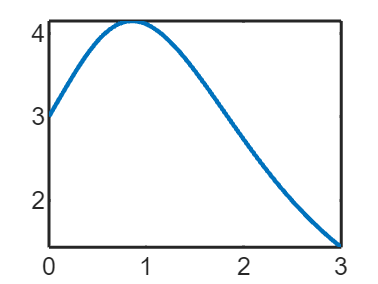

fplot(f,[0,3])